Implement E[LB_∞]  in MATLAB by Numerical Integration by **MATLAB’s built‐in** `integral function`

** Continuous Lower Bound Formula (7)**

% use intergration function from matlab 
sigma = 0.3; K=100; T=1; S0=100; r=0.04;

tic
LB_conti=  LB_continuous(S0,K,r,sigma,T)

LB_conti =         7.727


toc

Elapsed time is 0.401349 seconds.



function LB_infinity =  LB_continuous(S0,K,r,sigma,T)
    gamma = ( log(K/S0) - (r - 0.5*sigma^2)*(T/2) ) / sigma;
    integrand = @(t) exp(-r*(T - t)) .* normcdf(  (-gamma + sigma*t- (sigma*t.^2)/(2*T) ) / (sqrt(T/3)));
    int_val = integral(integrand, 0, T); 
    LB_infinity = (S0/T)*int_val - K*exp(-r*T) * normcdf( -gamma * sqrt(3/T));
end

startCPU = cputime

startCPU =        534.15


LB_conti=  LB_continuous(S0,K,r,sigma,T)

LB_conti =         7.727


cputime - startCPU

ans =          0.04


**Code below compute **

**Continuous lower bound formula (7)** using the trapezoidal rule for numerical integration.

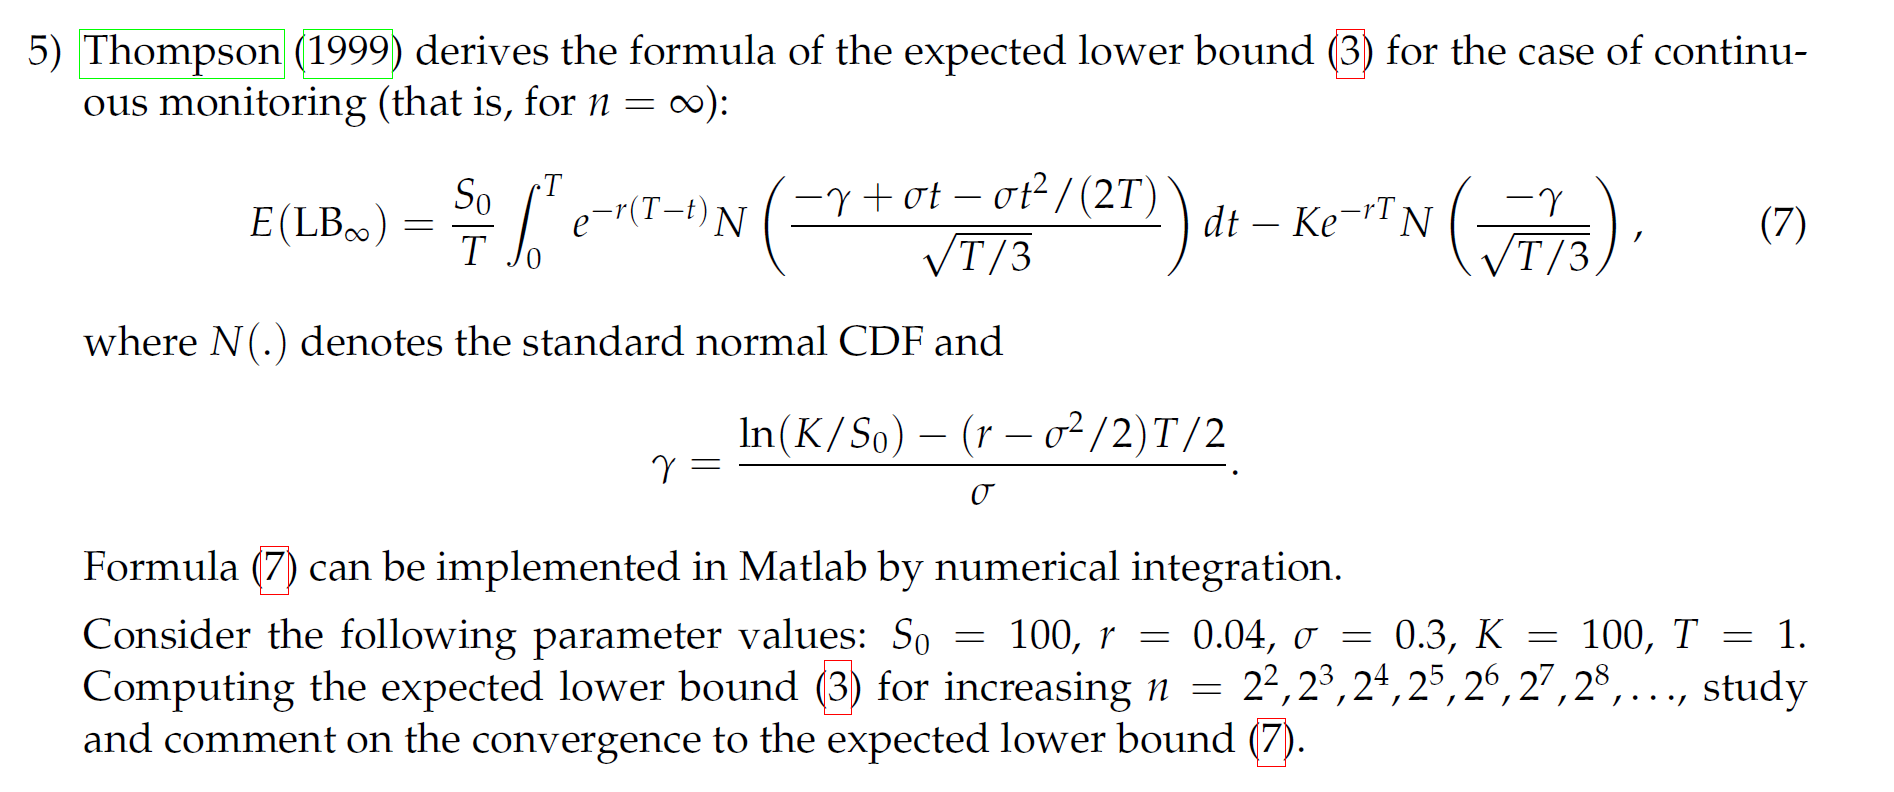

S0 = 100; r = 0.04; sigma = 0.3; K = 100; T = 1;
n_values = 2.^(2:20);
LB_conti_Tra = zeros(size(n_values));
timeAr_conti_Tra = zeros(size(n_values));

for i = 1:length(n_values)
    n = n_values(i);
    tic;
    LB_conti_Tra(i) = LBinf_Conti_Trapezoid(S0, K, r, sigma, T,n);
    timeAr_conti_Tra(i)=toc;
end

LB_conti_Tra

LB_conti_Tra =        7.6258       7.7017       7.7206       7.7254       7.7266       7.7269       7.7269        7.727        7.727        7.727        7.727        7.727        7.727        7.727        7.727        7.727        7.727        7.727        7.727


size(LB_conti_Tra)

ans =      1    19


timeAr_conti_Tra

timeAr_conti_Tra =     0.0018013   0.00046346   0.00033874   0.00029704    0.0032888   0.00018523    0.0015701   0.00021266   7.8891e-05   0.00091588   0.00084372   0.00069381    0.0031942    0.0095643    0.0087421      0.01533     0.039254      0.11087      0.12598




function LBinf_trap = LBinf_Conti_Trapezoid(S0, K, r, sigma, T,n)
    dt = T / n; % time step
    t = 0 : dt : T;
    gamma = (log(K/S0) - (r - 0.5*sigma^2)*(T/2)) / sigma;
    integrand = exp(-r*(T - t)) .* normcdf((-gamma + sigma*t - (sigma*t.^2)/(2*T)) / sqrt(T/3));
    
    % Trapezoidal rule
    weights = dt * ones(size(t));
    weights(1) = 0.5 * dt;
    weights(end) = 0.5 * dt;
    integral_value = sum(integrand .* weights);
    LBinf_trap = (S0 / T) * integral_value - K * exp(-r*T) * normcdf(-gamma / sqrt(T/3));
end

** Discrete Lower Bound Formula (3)**

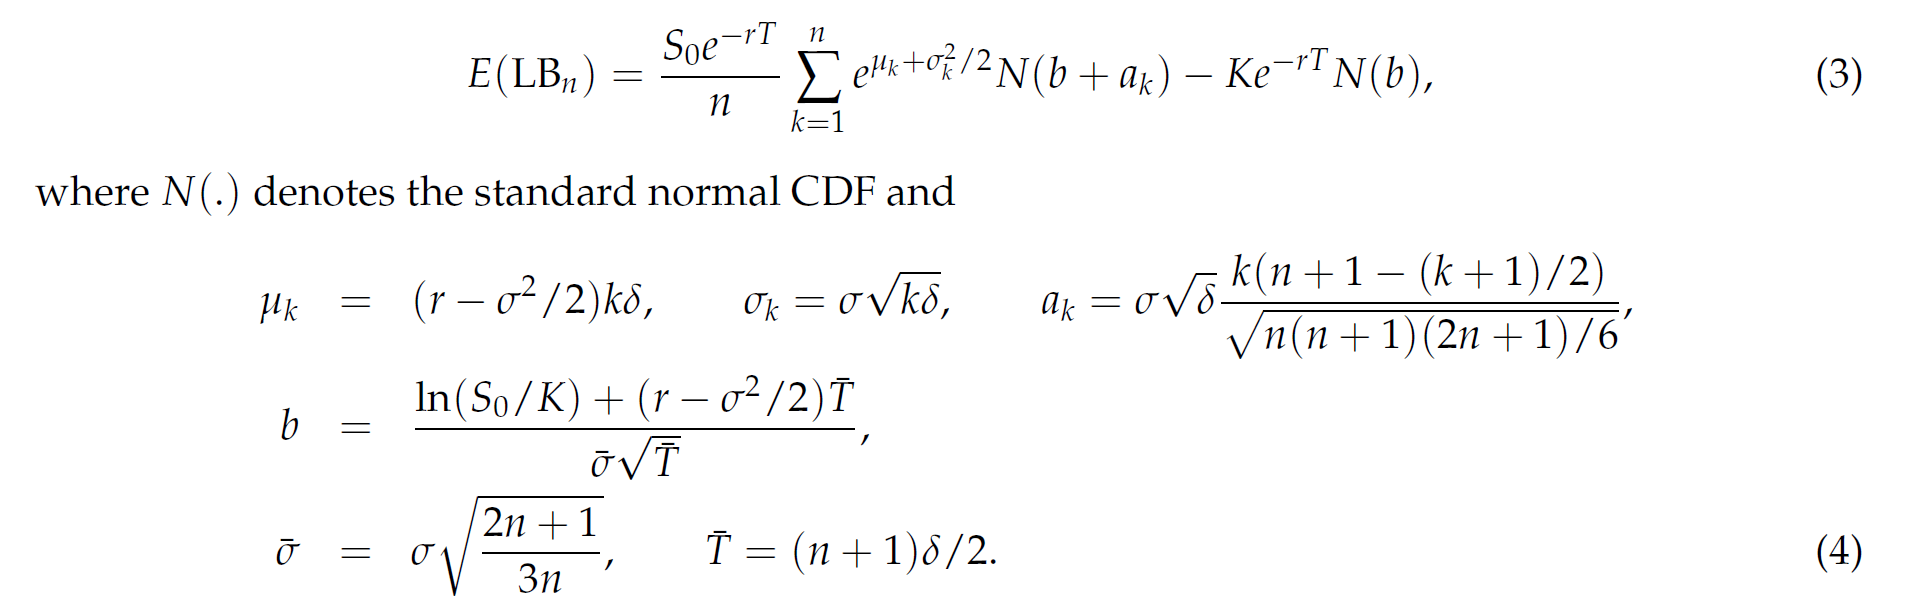


S0 = 100; r = 0.04; sigma = 0.3; K = 100; T = 1;
n_values = 2.^(2:20); 

timeAr_LB_discrete = zeros(size(n_values));
LB_discrete = zeros(size(n_values));

for i = 1:length(n_values)
    n = n_values(i);
    tic
    LB_discrete(i) = lowerbound(S0, r, sigma, K, T, n);
    timeAr_LB_discrete(i)=toc;
end
LB_discrete

LB_discrete =        9.2449       8.4877       8.1078       7.9175       7.8223       7.7746       7.7508       7.7389       7.7329       7.7299       7.7285       7.7277       7.7273       7.7271       7.7271        7.727        7.727        7.727        7.727




function LB = lowerbound(S0,r,sigma,K,T,n)
% K is strike price
% k (lowercase) is the index in the summation 

ts = T/n; % time step size δ 
That = (n+1)*ts/2;
sigma_hat = sigma*sqrt((2*n+1)/(3*n));
b=(log(S0/K)+(r-0.5*sigma^2)*That)/(sigma_hat*sqrt(That));

mid=0;
for k =1:1:n
    miu_k = (r-0.5*sigma^2)*k*ts;
    sigma_k = sigma*sqrt(k*ts);
    ak = sigma *sqrt(ts) * ((k * (n + 1 - (k + 1)/2) / sqrt (n*(n+1)*(2*n+1)/6)));
    mid = mid + exp(miu_k+ 0.5*sigma_k^2)*normcdf(b+ak);
end
LB = S0*exp(-r*T)/n * mid -K*exp(-r*T)*normcdf(b);
end


% Display results
disp(table(LB_conti, 'VariableNames', {'Continous LB (built-in)'}))

    Continous LB (built-in)
    _______________________

             7.727         



disp(table(n_values(:), LB_discrete(:), LB_conti_Tra(:), (LB_discrete(:) - LB_conti_Tra(:)),timeAr_LB_discrete',timeAr_conti_Tra','VariableNames', {'n','Discrete LB','Continuous LB(Trapezoid)','Difference','Time(Discrete)','Time(Continuous)'}));

        n         Discrete LB    Continuous LB(Trapezoid)    Difference    Time(Discrete)    Time(Continuous)
    __________    ___________    ________________________    __________    ______________    ________________

             4      9.2449                7.6258                 1.6192       0.0021312          0.0018013   
             8      8.4877                7.7017                0.78601       0.0017284         0.00046346   
            16      8.1078                7.7206                0.38719      0.00040708         0.00033874   
            32      7.9175                7.7254                0.19215      0.00046691         0.00029704   
            64      7.8223                7.7266               0.095717       0.0024771          0.0032888   
           128      7.774

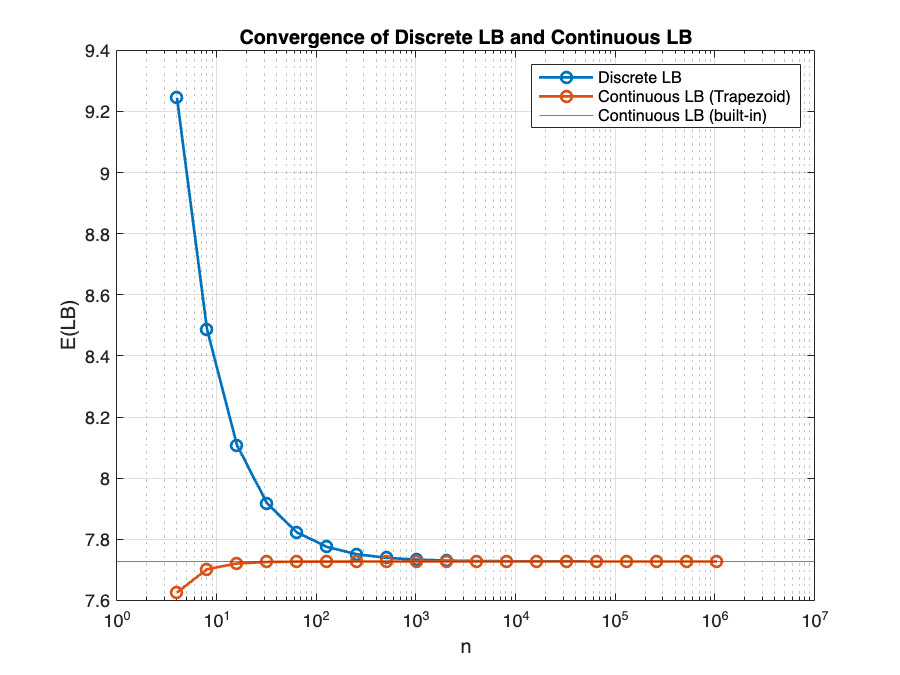


% Plot convergence
figure;
semilogx(n_values, LB_discrete, 'o-', 'LineWidth', 1.5);
hold on;
semilogx(n_values, LB_conti_Tra, 'o-', 'LineWidth', 1.5);
yline(LB_conti,'Color','r')
xlabel('n');
ylabel('E(LB)');
legend('Discrete LB', 'Continuous LB (Trapezoid)','Continuous LB (built-in) ');
title('Convergence of Discrete LB and Continuous LB');
grid on;

% test for cpu time only
LB_discrete = zeros(size(n_values));
CPUTime_LB_discrete = zeros(size(n_values));
for i = 1:length(n_values)
    n = n_values(i);
    startcpu = cputime;
    LB_discrete(i) = lowerbound(S0, r, sigma, K, T, n);
    CPUTime_LB_discrete(i)= cputime-startcpu;
end
CPUTime_LB_discrete

CPUTime_LB_discrete =          0.01            0            0            0            0         0.01            0         0.01         0.08         0.05         0.06         0.07         0.11         0.24         0.94         0.79         1.54         3.39          7.7




% TEST on CPU time only

S0 = 100; r = 0.04; sigma = 0.3; K = 100; T = 1;
n_values = 2.^(2:20);
LB_conti_Tra = zeros(size(n_values));
CPU_time_conti_Tra = zeros(size(n_values));

for i = 1:length(n_values)
    n = n_values(i);
    startCPU = cputime;
    LB_conti_Tra(i) = LBinf_Conti_Trapezoid(S0, K, r, sigma, T,n);
    CPU_time_conti_Tra(i)=cputime-startCPU;
end

CPU_time_conti_Tra

CPU_time_conti_Tra =             0         0.01            0            0            0            0            0            0         0.01            0            0            0            0         0.01            0         0.03         0.03         0.04         0.11


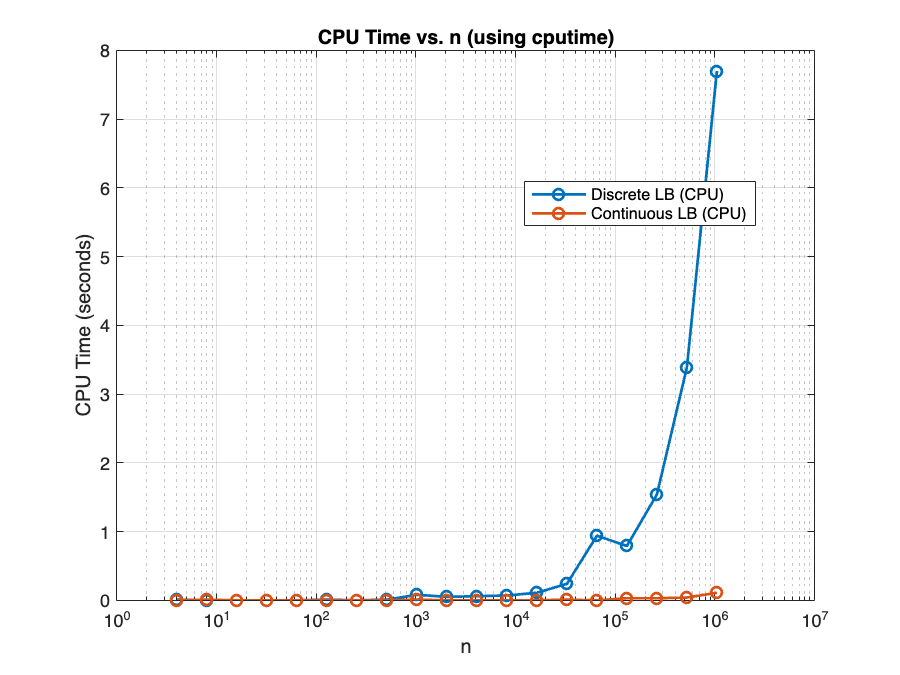




figure;

semilogx(n_values, CPUTime_LB_discrete, 'o-', 'LineWidth', 1.5);
hold on;
semilogx(n_values, CPU_time_conti_Tra, 'o-', 'LineWidth', 1.5);

xlabel('n');
ylabel('CPU Time (seconds)');
legend('Discrete LB (CPU)','Continuous LB (CPU)','Location','best');
title('CPU Time vs. n (using cputime)');
grid on;

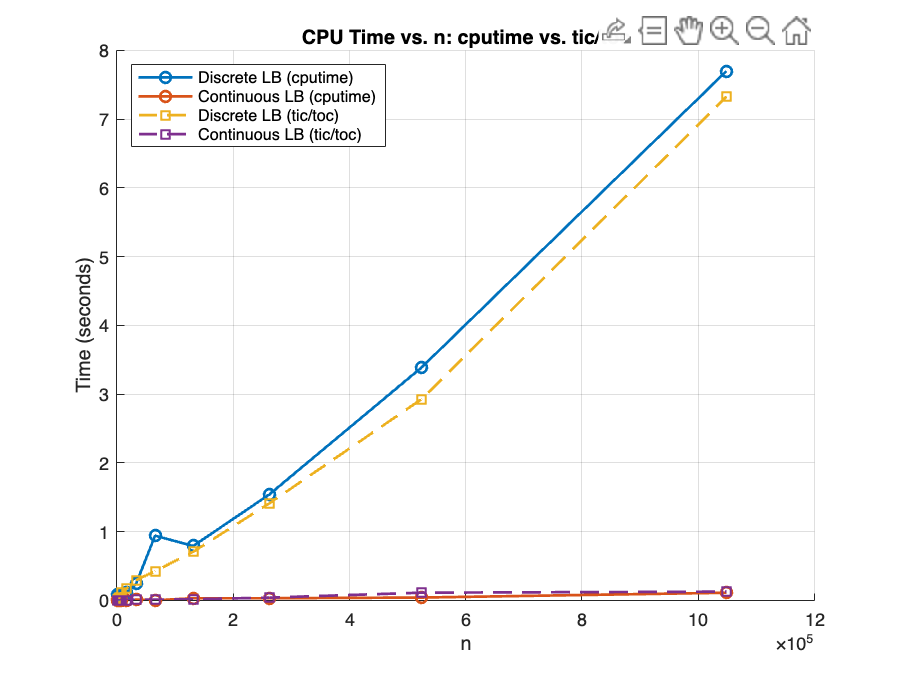

figure;
hold on;  

% Discrete LB using cputime
semilogx(n_values, CPUTime_LB_discrete, 'o-', 'LineWidth', 1.5);
% Continuous LB using cputime
semilogx(n_values, CPU_time_conti_Tra, 'o-', 'LineWidth', 1.5);

% Discrete LB using tic/toc
semilogx(n_values, timeAr_LB_discrete, 's--', 'LineWidth', 1.5);
% Continuous LB using tic/toc
semilogx(n_values, timeAr_conti_Tra, 's--', 'LineWidth', 1.5);

hold off;

xlabel('n');
ylabel('Time (seconds)');
title('CPU Time vs. n: cputime vs. tic/toc');
legend(...
  'Discrete LB (cputime)', ...
  'Continuous LB (cputime)', ...
  'Discrete LB (tic/toc)', ...
  'Continuous LB (tic/toc)', ...
  'Location','northwest');
grid on;

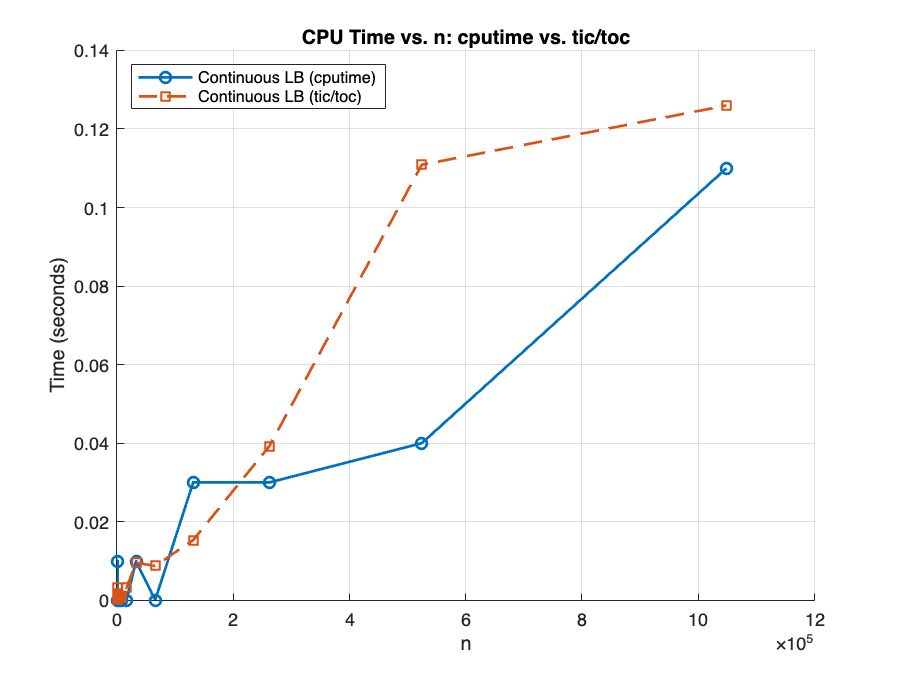

figure;
hold on;  


% Continuous LB using cputime
semilogx(n_values, CPU_time_conti_Tra, 'o-', 'LineWidth', 1.5);
% Continuous LB using tic/toc
semilogx(n_values, timeAr_conti_Tra, 's--', 'LineWidth', 1.5);

hold off;

xlabel('n');
ylabel('Time (seconds)');
title('CPU Time vs. n: cputime vs. tic/toc');
legend(...
  'Continuous LB (cputime)', ...
  'Continuous LB (tic/toc)', ...
  'Location','northwest');
grid on;